Choose your matrix.

A=sym([1 1;0 1])

$$A = \left(\begin{array}{cc} 1 & 1\\ 0 & 1 \end{array}\right)$$

[S, D] = eig(A)

$$S = \left(\begin{array}{c} 1\\ 0 \end{array}\right)$$

$$D = \left(\begin{array}{cc} 1 & 0\\ 0 & 1 \end{array}\right)$$

ans = logical
   0


Here is a picture of the phase plane with eigenspaces indicated if the eigenvalues are real.

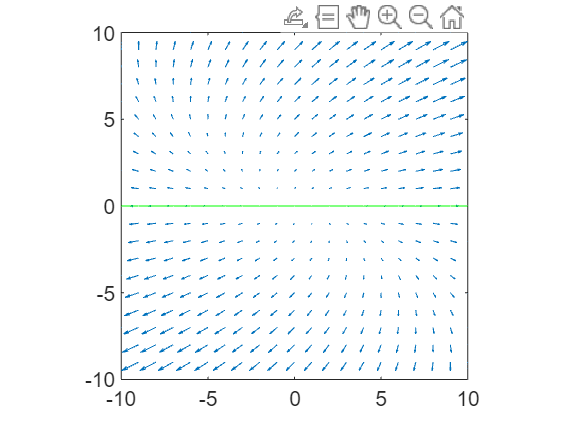

N = 10;
xs = -N:1:N;
[X,Y] = meshgrid(xs);
B = A*[X(:)'; Y(:)'];
U = reshape(B(1,:)', size(X));
V = reshape(B(2,:)', size(Y));
fig1 = figure(1);
clf(fig1);
quiver(X,Y,U,V)
axis([-N N -N N])
daspect([1 1 1])
hold on
if D == real(D)
    Q = [xs; xs].*S(:,1);
    plot(Q(1,:), Q(2,:), "-g")
    if all(size(S) == [2 2])
        Q = [xs; xs].*S(:,2);
        plot(Q(1,:), Q(2,:), "-c")
    end
end

You can change a and b below and re-run the cell to add several solutions with different starting values. This generates a piecewise approximation to a solution by connecting points


$$\left\lbrack \begin{array}{c}
y_1 \left(n+1\right)\\
y_2 \left(n+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_1 \left(n\right)\\
y_2 \left(n\right)
\end{array}\right\rbrack +A\left\lbrack \begin{array}{c}
y_1 \left(n\right)\\
y_2 \left(n\right)
\end{array}\right\rbrack \cdot \Delta x$$


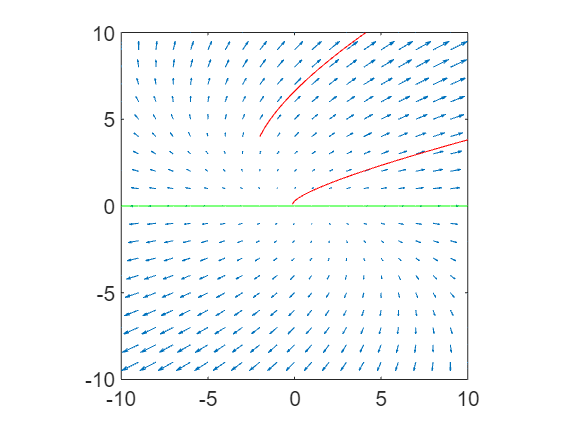

delta = 0.01;
a = -2; b = 4;
y0 = [a; b];
P = zeros([2 1000]);
P(:,1) = y0;
for i = 2:1000
    P(:,i) = P(:,i - 1)+A*P(:, i - 1)*delta;
end
plot(P(1,:),P(2,:),"-r")

Plot the actual solution 


$$\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =e^{\textrm{At}} \left\lbrack \begin{array}{c}
y_1 \left(0\right)\\
y_2 \left(0\right)
\end{array}\right\rbrack$$


over the interval [-N, N].

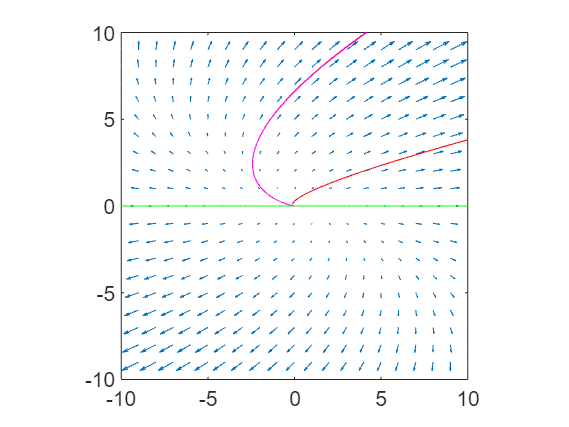

xss = linspace(-N, N,300);
Q = zeros([2 300]);
for i = 1:300
    Q(:,i) = expm(A.*xss(i))*y0;
end
plot(Q(1,:),Q(2,:),"-m")